s = [1,1,2,2,3,3,4,4,4,5];
t = [2,3,4,5,4,7,5,6,7,6];
weights = [50,60,65,40,52,45,50,30,42,70];
% 生成无向图，其中s和t对应元素代表边，weights是权值
G = graph(s,t,weights);
% 求出最小生成树，得到的T包含最小生成树的节点和对应边的权值
T = minspantree(G);

% p = plot(G)可以把图片展现出来
p = plot(G,'EdgeLabel',G.Edges.Weight)

p =   GraphPlot - 属性:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'1'  '2'  '3'  '4'  '5'  '6'  '7'}
     EdgeLabel: {'50'  '60'  '65'  '40'  '52'  '45'  '50'  '30'  '42'  '70'}
         XData: [-1.8494 -0.6003 -0.8301 0.4424 0.7618 1.8352 0.2404]
         YData: [0.0561 0.8945 -1.0007 -0.1264 1.2033 0.6469 -1.6738]
         ZData: [0 0 0 0 0 0 0]

  显示 所有属性


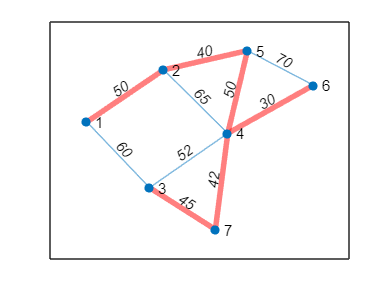

% 突出显示绘制的图中的节点和边
highlight(p,T,'EdgeColor','red','LineWidth',3)